A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2



i = logical([1 1 1;1 1 0;1 1 1])

i = 3×3 logical array
   1   1   1
   1   1   0
   1   1   1


A(i)

ans =      8
     3
     4
     1
     5
     9
     6
     2



i1 = logical([1 0 1])

i1 = 1×3 logical array
   1   0   1


i2 = logical([1 1 1])

i2 = 1×3 logical array
   1   1   1


A(i1,i2)

ans =      8     1     6
     4     9     2




i = logical([1 1 1;1 1 1;1 1 1])

i = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1


A(i)

ans =      8
     3
     4
     1
     5
     9
     6
     7
     2


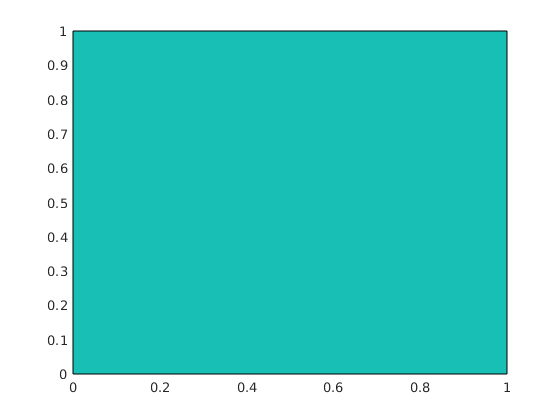

% patch([0 1 1 0],[0 0 1 1],[0 1 1 0])
% figure
% patch([0 1 1 0],[0 0 1 1],[1 2 2 1])
% figure
% patch([0 1 1 0],[0 0 1 1],[1 2 2 2])
figure
patch([0 1 1 0]',[0 0 1 1]',1)

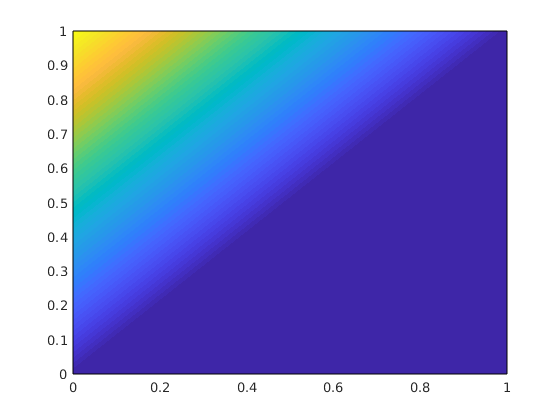

figure
patch([0 1 1 0]',[0 0 1 1]',[1 1 1 2]')

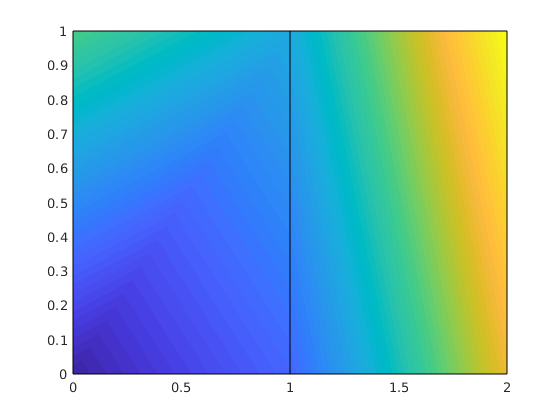

figure
h=patch([0 1 1 0;1 2 2 1]',...
        [0 0 1 1;0 0 1 1]',...
        [1 2 3 4;2 5 6 3]');

h.Faces

ans =      1     2     3     4
     5     6     7     8


h.Vertices

ans =      0     0
     1     0
     1     1
     0     1
     1     0
     2     0
     2     1
     1     1


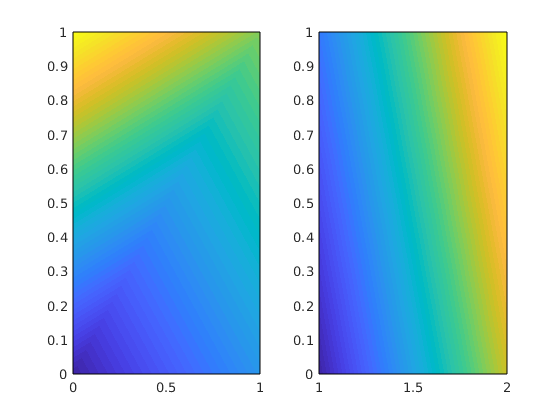

%% This is homogenous, different than if they were separate:
figure
subplot(1,2,1)
h=patch([0 1 1 0]',...
        [0 0 1 1]',...
        [1 2 3 4]');
subplot(1,2,2)
h=patch([1 2 2 1]',...
        [0 0 1 1]',...
        [2 5 6 3]');

    syms r s 
N1 = 0.25*(1-r)*(1-s)

$$N1 = \left(\frac{r}{4}-\frac{1}{4}\right)\,\left(s-1\right)$$

N2 = 0.25*(1+r)*(1-s)

$$N2 = -\left(\frac{r}{4}+\frac{1}{4}\right)\,\left(s-1\right)$$

N3 = 0.25*(1+r)*(1+s)

$$N3 = \left(\frac{r}{4}+\frac{1}{4}\right)\,\left(s+1\right)$$

N4 = 0.25*(1-r)*(1+s)

$$N4 = -\left(\frac{r}{4}-\frac{1}{4}\right)\,\left(s+1\right)$$

subs(N1,[r s],[-1 -1])

$$ans = 1$$

subs(N2,[r s],[ 1 -1])

$$ans = 1$$

subs(N3,[r s],[ 1  1])

$$ans = 1$$

subs(N4,[r s],[-1  1])

$$ans = 1$$


r1 = -1/sqrt(3);
s1 = -1/sqrt(3);
r2 =  1/sqrt(3);
s2 = -1/sqrt(3);
r3 =  1/sqrt(3);
s3 =  1/sqrt(3);
r4 = -1/sqrt(3);
s4 =  1/sqrt(3);
[double(subs(diff(N1,r), [r s], [r1 s1])),...
double(subs(diff(N2,r), [r s], [r1 s1])),...
double(subs(diff(N3,r), [r s], [r1 s1])),...
double(subs(diff(N4,r), [r s], [r1 s1]))
double(subs(diff(N1,s), [r s], [r1 s1])),...
double(subs(diff(N2,s), [r s], [r1 s1])),...
double(subs(diff(N3,s), [r s], [r1 s1])),...
double(subs(diff(N4,s), [r s], [r1 s1]))]

ans =    -0.3943    0.3943    0.1057   -0.1057
   -0.3943   -0.1057    0.1057    0.3943


s = 1/sqrt(3);
X= [-s  s s -s]';
Y= [-s -s s  s]';
C= [1 2 3 2]';
h=patch(X,Y,C)

h =   Patch with properties:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


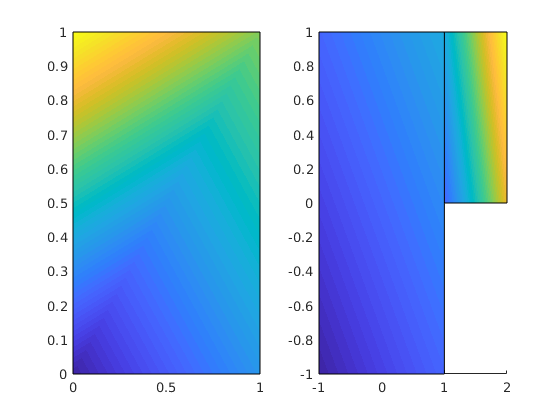

h.Vertices = [-1 -1;1 -1; 1 1; -1 1];

h.CData

ans =      1
     2
     3
     2


h.XData

ans =     -1
     1
     1
    -1


h.FaceVertexCData

ans =      1
     2
     3
     2


syms mat voigt
mat = sym('sigma',3)

$$mat = \left(\begin{array}{ccc} \sigma_{1,1} & \sigma_{1,2} & \sigma_{1,3}\\ \sigma_{2,1} & \sigma_{2,2} & \sigma_{2,3}\\ \sigma_{3,1} & \sigma_{3,2} & \sigma_{3,3} \end{array}\right)$$

voigt = mat([1,5,9,4,8,7])

$$voigt = \left(\begin{array}{cccccc} \sigma_{1,1} & \sigma_{2,2} & \sigma_{3,3} & \sigma_{1,2} & \sigma_{2,3} & \sigma_{1,3} \end{array}\right)$$

reshape(voigt([1,4,6,4,2,5,6,5,3]),3,3)

$$ans = \left(\begin{array}{ccc} \sigma_{1,1} & \sigma_{1,2} & \sigma_{1,3}\\ \sigma_{1,2} & \sigma_{2,2} & \sigma_{2,3}\\ \sigma_{1,3} & \sigma_{2,3} & \sigma_{3,3} \end{array}\right)$$

A = [1  2  0  0  0  0
     4  5  6  0  0  0
     0  7  8  9  0  0
     0  0 10 11 12  0
     0  0  0 13 14 15
     0  0  0  0 16 17];
A = A*A;
 
B = sparse(A);
C = [1 2 3 4 5 6]';
A*C

ans =           69
         624
        2022
        4758
        7440
        6486


B*C

ans =           69
         624
        2022
        4758
        7440
        6486


fileID = fopen('nine.bin','w');
fwrite(fileID,[1:9]);
fclose(fileID);
